# Exercise #1: Simulate an Ideal Scenario

In this exercise, you will simulate an earth observation mission. A satellite will perform a flyover of a region of the Amazon Rainforest to capture images of the area, and then will downlink the images to a ground station in Svalbard, Norway. When not pointing at one of these two locations, the satellite will point back at the nadir.  

## Part 1: Simulate the mission

In this part you will

- Define the mission parameters

- Open and run the simulation

- Show the simulated mission in a Satellite Scenario

- Review results and close windows

### **1) Define the mission parameters**

**Run this section** to define the mission parameters and open the simulation model.

% Define mission start and end time
missionstartdate = datetime(2021,1,1,12,0,0);
missionduration = hours(1.5);

% Define the locations we'll need our satellite to point towards
targetNO = [78, 21, 0]; % lat, lon, altitude of Svalbard, NO
targetAmazon = [-4.9, -66, 0]; % lat, lon, altitude of Amazon Rainforest, BR

### 2) Open and run the simulation

**Run this section** to open the model. 

open_system Exercise1

In the Simulink window that opens, **run the model. **

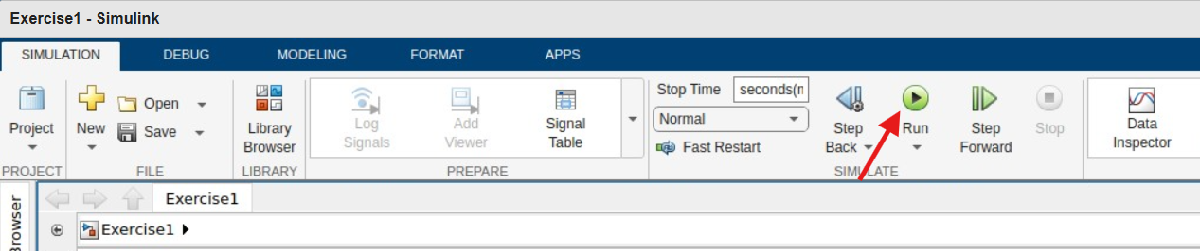

**Open the Data Inspector** to see how our spacecraft rotates over time for this mission. You'll notice there's two distinct slews - to and from the Amazon Rainforest location around 2500 seconds, and to and from the Norway ground station around 4000 seconds. 

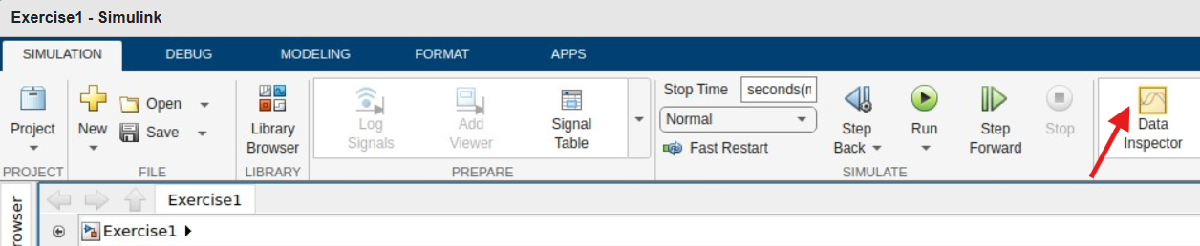

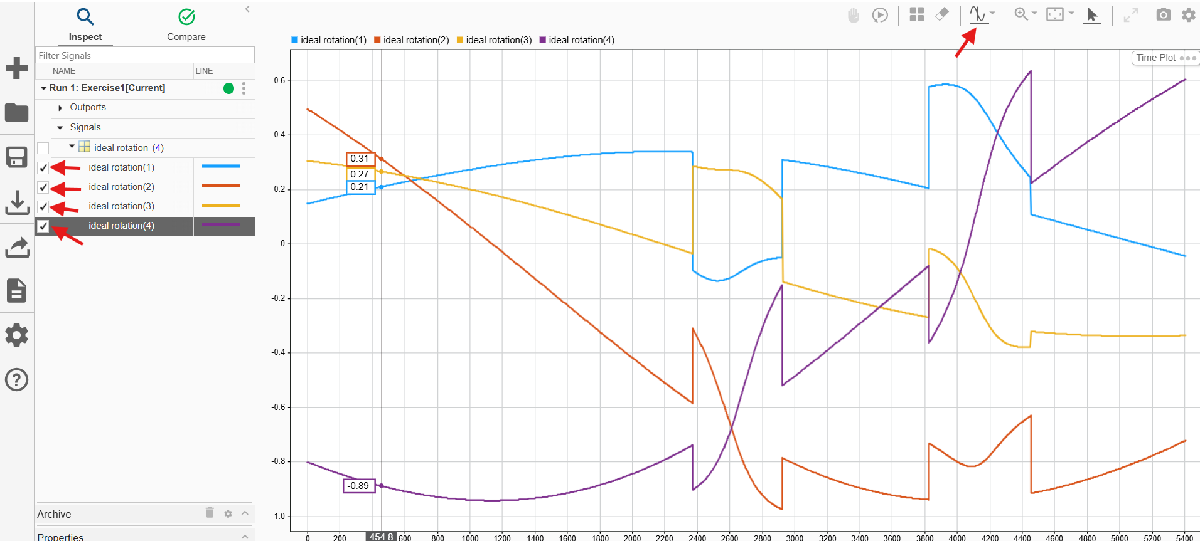

### 3) Show the simulated mission in a Satellite Scenario

We can also quickly create a higher-fidelity visualization of the mission using a [satellite scenario](https://www.mathworks.com/help/aerotbx/ug/satellitescenario.html) object. 

**Run this section** to see the visualization. For this visualization, we'll use the data from the Simulink model run previously to populate the satellite's attitude and ephemeris. 

% Create scenario
scenario = satelliteScenario(missionstartdate,missionstartdate+missionduration,1);

% Add target points for slews to scenario
gsNO = groundStation(scenario,targetNO(1),targetNO(2),Name="Svalbard, NO");
gsAmazon = groundStation(scenario,targetAmazon(1),targetAmazon(2),Name="Amazon Rainforest");

% Get satellite data from simulation
idealSatEphemeris = retime(out.yout{1}.Values,seconds(uniquetol(out.tout, 0.0001)));
idealSatAttitude = retime(out.yout{3}.Values,seconds(uniquetol(out.tout, 0.0001)));

% Add satellite to scenario
sat = satellite(scenario,idealSatEphemeris,"CoordinateFrame","inertial","Name","Satellite");
sens = conicalSensor(sat);
pointAt(sat, idealSatAttitude, "CoordinateFrame", "inertial", "Format", "quaternion", "ExtrapolationMethod", "fixed");
ac = access(sens,[gsNO gsAmazon]');

% View
viewer = satelliteScenarioViewer(scenario);
sat.Visual3DModel = "SmallSat.glb";
coordinateAxes(sat, Scale=2);
play(scenario,PlaybackSpeedMultiplier=75);
camtarget(viewer,sat);

% Access Line-of-Sight Data
interval = accessIntervals(ac)

While the Satellite Scenario will start to play automatically, keep in mind the controls available to play the scenario at different speeds, forwards or backwards.

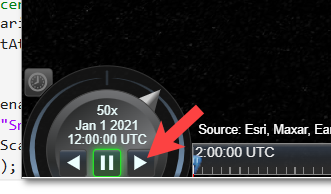

You can also click the Home button to see a full-globe view.

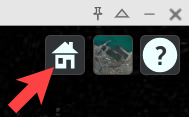

### 4) Review results and close windows

In this exercise, we simulated an ideal mission, with the assumption our spacecraft would be able to point exactly where we need it to for imaging and downlinking. To successfully complete this mission, we'll need to design a control system that can accurately point the spacecraft within our performance constraints. In the next exercise, we'll explore how we can design and tune a controller for this purpose.

**Close the Satellite Scenario viewer.**

Then, **run this section** to close this exercise's model and open the live script for the next exercise.

close_system("Exercise1",0)
open Exercise2.mlx